close all
clear all
Data=xlsread('20250523_frequency_test_1.csv');
st=1;
ed=5;
int=5;
c=1;
for i=1:length(Data)
    a1=Data(i,1);
    if ~isnan(a1)
        ini_index(c)=i+2;
        c=c+1;
        i=i+1;
    else
        i=i+1;
    end
end
%%4-layer||4-layer
A1=Data(1:ini_index(ed)-3,:);
[yave1,dave1,Y1,pos1]=data_ave_and_bocplot(A1);
figure('DefaultAxesFontSize',16,'Position',[200 200 600 480]);
color.code=colormap(slanCM(160));

@author : slandarer


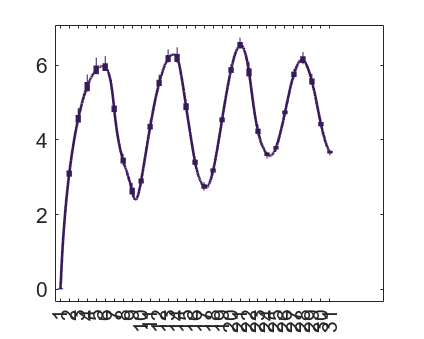

color.l=length(color.code);
color.index1=round(color.l*2/9);
plot(dave1,yave1,'Color',color.code(color.index1,:),'LineWidth',2);
hold on
boxplot(Y1,'Positions',pos1,'Colors',color.code(color.index1,:),'BoxStyle','filled','Widths',0.5,'Symbol','');

yave11=yave1/2;
st=st+int;
ed=ed+int;
%% 4-layer||2-layer
figure('DefaultAxesFontSize',16,'Position',[200 200 600 480]);
color.code=colormap(slanCM(160));

@author : slandarer


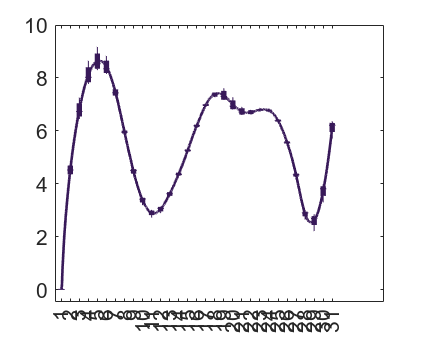

color.l=length(color.code);
color.index1=round(color.l*2/9);
A2=Data(ini_index(st)-2:ini_index(ed)-3,:);
[yave2,dave2,Y2,pos2]=data_ave_and_bocplot(A2);
plot(dave2,yave2,'Color',color.code(color.index1,:),'LineWidth',2);
hold on
boxplot(Y2,'Positions',pos2,'Colors',color.code(color.index1,:),'BoxStyle','filled','Widths',0.5,'Symbol','');

st=st+int;
ed=ed+int;
%%4-layers||1-layer
figure('DefaultAxesFontSize',16,'Position',[200 200 600 480]);
color.code=colormap(slanCM(160));

@author : slandarer


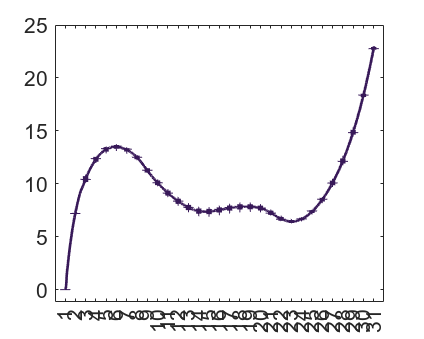

color.l=length(color.code);
color.index1=round(color.l*2/9);
A3=Data(ini_index(st)-2:ini_index(ed)-3,:);
[yave3,dave3,Y3,pos3]=data_ave_and_bocplot(A3);
plot(dave3,yave3,'Color',color.code(color.index1,:),'LineWidth',2);
hold on
boxplot(Y3,'Positions',pos3,'Colors',color.code(color.index1,:),'BoxStyle','filled','Widths',0.5,'Symbol','');

st=st+int;
ed=ed+int;
%%1-layer
figure('DefaultAxesFontSize',16,'Position',[200 200 600 480]);
color.code=colormap(slanCM(160));

@author : slandarer


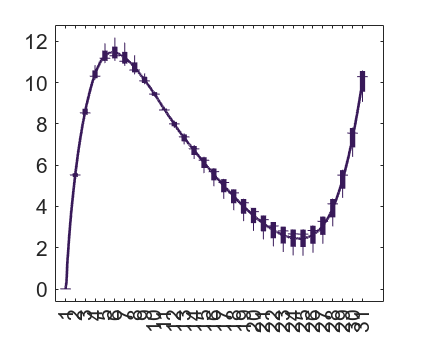

color.l=length(color.code);
color.index1=round(color.l*2/9);
A4=Data(ini_index(st)-2:ini_index(ed)-3,:);
[yave4,dave4,Y4,pos4]=data_ave_and_bocplot(A4);
plot(dave4,yave4,'Color',color.code(color.index1,:),'LineWidth',2);
hold on
boxplot(Y4,'Positions',pos4,'Colors',color.code(color.index1,:),'BoxStyle','filled','Widths',0.5,'Symbol','');

st=st+int;
ed=ed+int;
%%2-layers
figure('DefaultAxesFontSize',16,'Position',[200 200 600 480]);
color.code=colormap(slanCM(160));

@author : slandarer


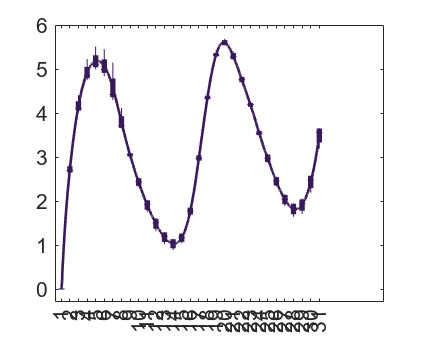

color.l=length(color.code);
color.index1=round(color.l*2/9);
A5=Data(ini_index(st)-2:ini_index(ed)-3,:);
[yave5,dave5,Y5,pos5]=data_ave_and_bocplot(A5);
plot(dave5,yave5,'Color',color.code(color.index1,:),'LineWidth',2);
hold on
boxplot(Y5,'Positions',pos5,'Colors',color.code(color.index1,:),'BoxStyle','filled','Widths',0.5,'Symbol','');

st=st+int;
ed=ed+int;

%%4-layers
figure('DefaultAxesFontSize',18,'Position',[200 200 800 600]);
color.code=colormap(slanCM(160));

@author : slandarer


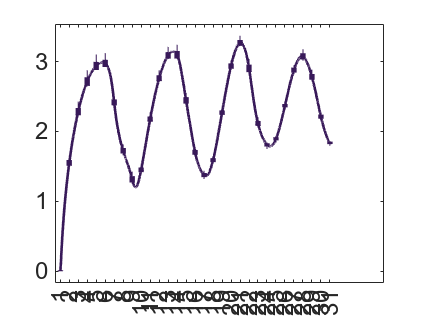

color.l=length(color.code);
color.index1=round(color.l*2/9);
plot(dave1,yave11,'Color',color.code(color.index1,:),'LineWidth',2);
hold on
boxplot(Y1/2,'Positions',pos1,'Colors',color.code(color.index1,:),'BoxStyle','filled','Widths',0.5,'Symbol','');


%%2-layers || 1-Layer
Data=xlsread('20250528_frequency_test_1.csv');
c=1;
ini_index=[];
for i=1:length(Data)
    a1=Data(i,1);
    if ~isnan(a1)
        ini_index(c)=i+2;
        c=c+1;
        i=i+1;
    else
        i=i+1;
    end
end
ll=length(ini_index);
st=1;
ed=5;
int=5;
%%2-layer||1-layer
A6=Data(ini_index(st)-2:ini_index(ed)-3,:);
[yave6,dave6,Y6,pos6]=data_ave_and_bocplot(A6);


%%Combine and Predict
figure('DefaultAxesFontSize',17,'Position',[200 200 600 480]);
color.code=colormap(slanCM(160));

@author : slandarer


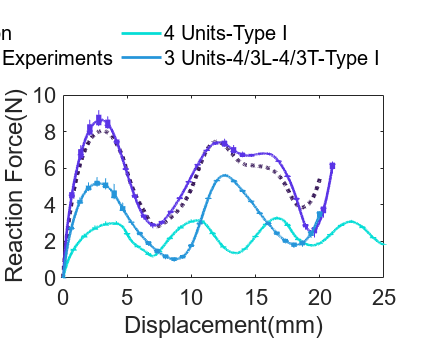

color.l=length(color.code);
color.index1=round(color.l*8/9);
color.index2=round(color.l*6/9);
color.index3=round(color.l*4/9);
color.index4=round(color.l*2/9);
[PD1,PY1]=parallized_prediction(dave1,dave5,yave11,yave5);
plot(PD1,PY1,'Color',color.code(color.index4,:),'LineWidth',3,'LineStyle',':');
hold on
plot(dave2,yave2,'Color',color.code(color.index3,:),'LineWidth',2);
hold on
boxplot(Y2,'Positions',pos2,'Colors',color.code(color.index3,:),'BoxStyle','filled','Widths',0.5,'Symbol','');
hold on
plot(dave1,yave11,'Color',color.code(color.index1,:),'LineWidth',2);
hold on
boxplot(Y1/2,'Positions',pos1,'Colors',color.code(color.index1,:),'BoxStyle','filled','Widths',0.5,'Symbol','');
hold on
plot(dave5,yave5,'Color',color.code(color.index2,:),'LineWidth',2);
hold on
boxplot(Y5,'Positions',pos5,'Colors',color.code(color.index2,:),'BoxStyle','filled','Widths',0.5,'Symbol','');
legend('Prediction','Parrallel Experiments','4 Units-Type I','3 Units-4/3L-4/3T-Type I');
legend('boxoff')
legend('FontName','Arial','Location','northoutside','NumColumns',2);
axis([0 25 0 10]);
xlabel('Displacement(mm)');
ylabel('Reaction Force(N)');
xticks(0:5:25)
yticks(0:2:10)
xticklabels({'0','5','10','15','20','25'})
ax=gca;
ax.FontName='Arial';

%%title('Frequecncy variation type 1');

figure('DefaultAxesFontSize',17,'Position',[200 200 600 480]);
color.code=colormap(slanCM(160));

@author : slandarer


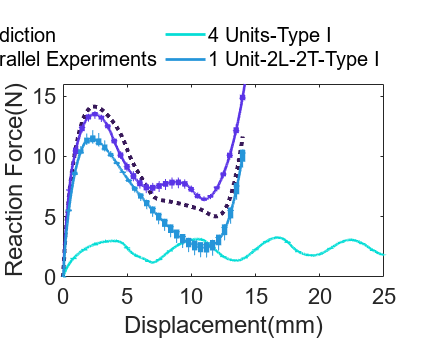

color.l=length(color.code);
color.index1=round(color.l*8/9);
color.index2=round(color.l*6/9);
color.index3=round(color.l*4/9);
color.index4=round(color.l*2/9);
[PD2,PY2]=parallized_prediction(dave1,dave4,yave11,yave4);
plot(PD2,PY2,'Color',color.code(color.index4,:),'LineWidth',3,'LineStyle',':');
hold on
plot(dave3,yave3,'Color',color.code(color.index3,:),'LineWidth',2);
hold on
boxplot(Y3,'Positions',pos3,'Colors',color.code(color.index3,:),'BoxStyle','filled','Widths',0.5,'Symbol','');
hold on
plot(dave1,yave11,'Color',color.code(color.index1,:),'LineWidth',2);
hold on
boxplot(Y1/2,'Positions',pos1,'Colors',color.code(color.index1,:),'BoxStyle','filled','Widths',0.5,'Symbol','');
hold on
plot(dave4,yave4,'Color',color.code(color.index2,:),'LineWidth',2);
hold on
boxplot(Y4,'Positions',pos4,'Colors',color.code(color.index2,:),'BoxStyle','filled','Widths',0.5,'Symbol','');
legend('Prediction','Parrallel Experiments','4 Units-Type I','1 Unit-2L-2T-Type I');
legend('boxoff')
legend('FontName','Arial','Location','northoutside','NumColumns',2);
axis([0 25 0 16]);
xlabel('Displacement(mm)');
ylabel('Reaction Force(N)');
xticks(0:5:25)
yticks(0:5:15)
xticklabels({'0','5','10','15','20','25'})
ax=gca;
ax.FontName='Arial';

%
figure('DefaultAxesFontSize',17,'Position',[200 200 600 480]);
color.code=colormap(slanCM(160));

@author : slandarer


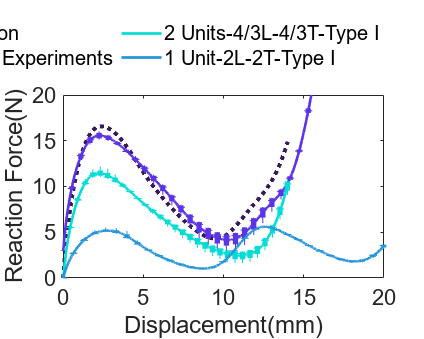

color.l=length(color.code);
color.index1=round(color.l*8/9);
color.index2=round(color.l*6/9);
color.index3=round(color.l*4/9);
color.index4=round(color.l*2/9);
[PD3,PY3]=parallized_prediction(dave4,dave5,yave4,yave5);
plot(PD3,PY3,'Color',color.code(color.index4,:),'LineWidth',3,'LineStyle',':');
hold on
plot(dave6,yave6+3,'Color',color.code(color.index3,:),'LineWidth',2);
hold on
boxplot(Y6+3,'Positions',pos6,'Colors',color.code(color.index3,:),'BoxStyle','filled','Widths',0.5,'Symbol','');
hold on
plot(dave4,yave4,'Color',color.code(color.index1,:),'LineWidth',2);
hold on
boxplot(Y4,'Positions',pos4,'Colors',color.code(color.index1,:),'BoxStyle','filled','Widths',0.5,'Symbol','');
hold on
plot(dave5,yave5,'Color',color.code(color.index2,:),'LineWidth',2);
hold on
boxplot(Y5,'Positions',pos5,'Colors',color.code(color.index2,:),'BoxStyle','filled','Widths',0.5,'Symbol','');

legend('Prediction','Parallel Experiments','2 Units-4/3L-4/3T-Type I','1 Unit-2L-2T-Type I');
legend('boxoff')
legend('FontName','Arial','Location','northoutside','NumColumns',2);
axis([0 20 0 20]);
xlabel('Displacement(mm)');
ylabel('Reaction Force(N)');
xticks(0:5:20)
yticks(0:5:20)
xticklabels({'0','5','10','15','20','25'})
ax=gca;
ax.FontName='Arial';